x=[-0.9 -0.7 -0.5 -0.3 -0.1 0.1 0.3 0.5 0.7 0.9];
y=[2 60 89 102 99 106 142 215 334 532];
dy=[2 8 4 10 8 15 5 8 15 20];
%tabela 5% istotności dla kolejnych stopni swobody
ist = [ 3.84146 5.99146 7.81473 9.48773 11.0705 12.5916 14.0671 15.5073  ];
Y=[];
chi = [];
for k = 1:8
    Y,beta=wielomian(x,y,dy,k);
    y_teo = polyval(flipud(beta),x); % współczyniki sa zwracane odwrontnie dlatego trzeba zrobić flipud()
    chi2= sum(((y-y_teo)/dy)^2);
    chi = [chi, chi2];
    if (chi2 < ist(k))
        break;
    end
end


Y =

     []


Y =

     []


Y =

     []



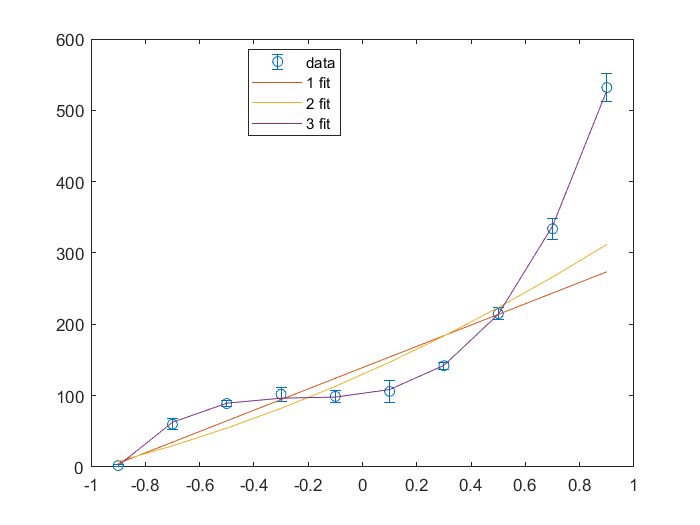


figure(1)
errorbar(x, y, dy, 'o')
hold on;
for i = 1:k
plot(x,wielomian(x,y,dy,i));
hold on;
end
legend('data', '1 fit', '2 fit', '3 fit', 'Location', 'best')

function[y,beta] = wielomian(x,y,dy,n)
p=(0:n)';
X=(x.^p)';
Omega=diag(dy)^2;
beta=inv((X')*inv(Omega)*(X))*(X')*inv(Omega)*y';
y=X*beta;
%beta
end